# Test valid position map

The goal of this script is to create the parts needed to create a valid position map. It can be asumed that the area where all the valid positions lie in is continous. Meaning that if we find the edges of this area we know all the valid positions. This way not every position has to be tested and thus we can save a lot of computation time and thus get a higher resolution.

This will be achieved in the following steps:

- Create a low resolution position map by testing all the positions

- Find the rough boundaries of the position map

- Using a binary search find the edges. 

- Visualize the area that the edges describe

### Setup

clear all; close all;
addpath("Kinematics")
addpath("Kinematics\Plotting")

## Low resolution valid position map

res = 2; 

The resolution is the most important variable, because the load scales kwadratically with this variable. Meaning if you take a resolution 10x larger the load is 100x larger. This is because we are exhaustively searching for a solution and this occurs in an area.

r_start = 80;
r_end = 260;
r_size = (r_end - r_start)/res + 1;
z_start = 0;
z_end = 130;
z_size = (z_end - z_start)/res + 1;
x = ArmPos();
tic

validPosmap1 = zeros(r_size,z_size);
for i=1:r_size
    r = r_start + i*res;
    for j=1:z_size
        z = z_start + j*res;
        pos = KineMod.IK_MAU([r,z],false);
        if pos.isvalid
            validPosmap1(i,j) = 1;
        end
    end
end
toc

Elapsed time is 2.722801 seconds.


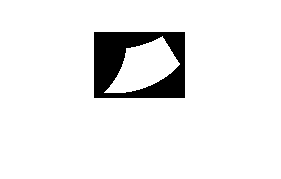

figure()
clf
imshow(flipud(transpose(validPosmap1)))

In the figure above there should be enough black padding surrounding the white area but as little as possible, then you have a good starting point for the bounding area.

## Using a binary search to find the edges of the valid area

We define an edge as being a point which to one side has a valid position and to the other side has an invalid position. 

To start the alogirthm of we need 2 invalid positions (we can use the bounding boxes found above) and one valid position which is in between the 2 invalid positions. Then we search the position in between the valid and invalid position and check wether it is valid or not. if it is valid we can use it as the new valid position and if it is invalid we use it as the new invalid position, and so on. 

First lets look at the typical case which would be in the middle of the valid position area.

### Boundary conditions check

z = (z_start + z_end)/2;

%checking if the edges are not valid, if they are valid the boundaries have
%not been set correctly
pos = KineMod.IK_MAU([r_start,z],false);
if pos.isvalid 
    error("Edges are valid, the boundaries are set incorrect")
end
pos = KineMod.IK_MAU([r_end,z],false);
if pos.isvalid 
    error("Edges are valid, the boundaries are set incorrect")
end

r = (r_end + r_start )/ 2;
pos = KineMod.IK_MAU([r,z],false);
if pos.isvalid ~= true 
    error("You need to fix this exception")
end
%next parellely search left and right of this position for the 

### Searching one line 

To see the difference in performance we search one line, and as can be seen it is quite fast

tic
acc = 0.1;
z = (z_end-z_start)/2;
VPBS.r_right(r,r_end,z,acc);
VPBS.r_left(r_start,r,z,acc);
toc

Elapsed time is 0.060331 seconds.


### Searching the whole area

tic
Ndec = 1; %amount of decimals acurracy we want
acc = 1*10^-Ndec; %accuracy in decimal shape
boundaries = zeros((z_end-z_start)/acc,2); %creating the array for storing the edges
r = (r_end+r_start)/2; %a guess of the initial valid position
for i=1:(z_end-z_start)/acc
    z = i*acc; %computing new z position
    boundaries(i,2) = VPBS.r_right(r,r_end,z,acc); %finding the right edge
    boundaries(i,1) = VPBS.r_left(r_start,r,z,acc); %finding the left edge
end
toc

Elapsed time is 8.129332 seconds.


tic
validPosmap2 = zeros((z_end-z_start)/acc+1,(r_end-r_start)/acc);
bounds = round(boundaries,Ndec, "decimals"); %rounding the boundaries of the the number of decimals
for i=1:length(boundaries)
    for j=bounds(i,1)*10^Ndec:bounds(i,2)*10^Ndec %multiplying the current bounds to get an integer value
        r = round(j); %converting the number to an integer value;
        validPosmap2(i,r) = 1;
    end
end
toc

Elapsed time is 0.040467 seconds.


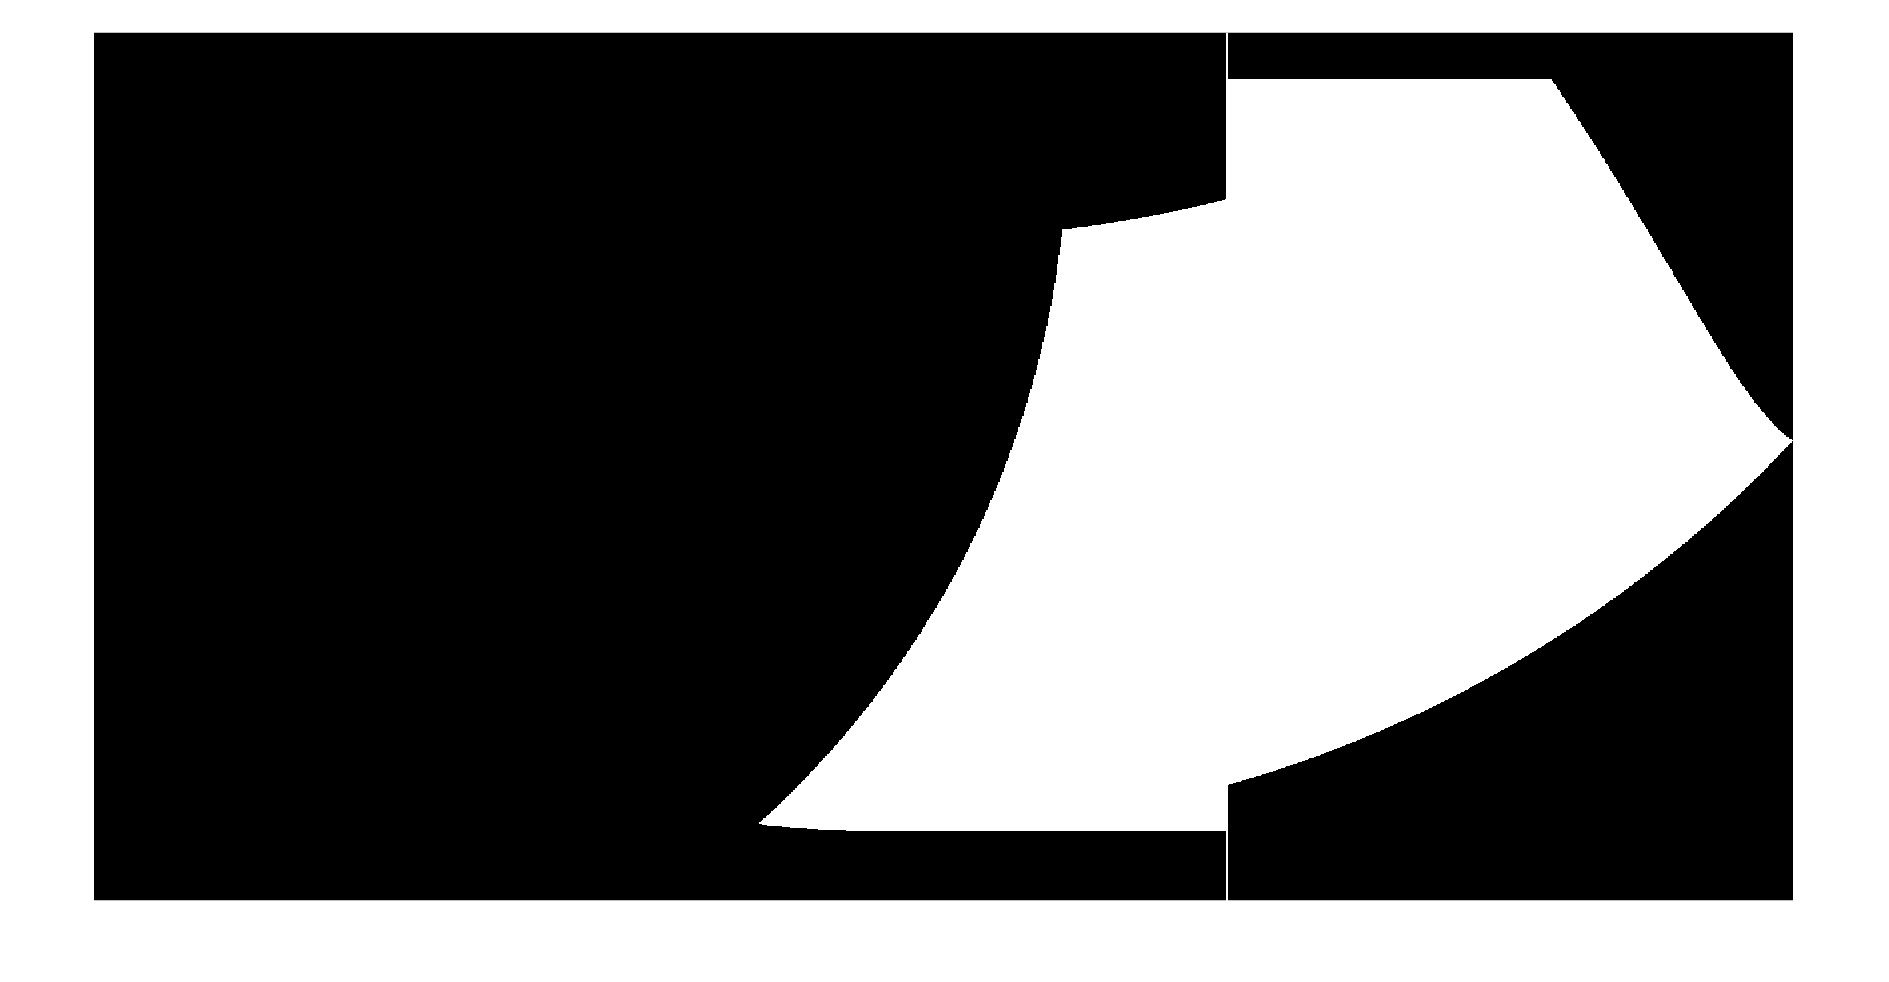

imshow(flipud((validPosmap2))) %creating the image

As can be seen in the figure above we have a nice high resolution of the valid position map.

But there is something clearly wrong, as can be seen when the binary search does not find anything it returns it's initial guess. Which if there are no solutions is fine. But if our guess is to far to the right for example for our right side search, we do not find a correct right side value. Meaning that we need to improve our first guess.

## Taking a better first guess

Instead of having a constant first guess we take a diagonal line acros the valid position area.

tic
Ndec = 1;
acc = 1*10^-Ndec;
boundaries = zeros((z_end-z_start)/acc,2);
r_mid = (r_end + r_start )/ 2;
z_mid = (z_end + z_start)/2;
f = (z_end-z_start)/(length(boundaries)-10);
for i=1:(z_end-z_start)/acc
    z = i*acc;
    r = r_mid + (z-z_mid);
    boundaries(i,2) = VPBS.r_right(r,r_end,z,acc);
    boundaries(i,1) = VPBS.r_left(r_start,r,z,acc); 
end
toc

Elapsed time is 6.076290 seconds.


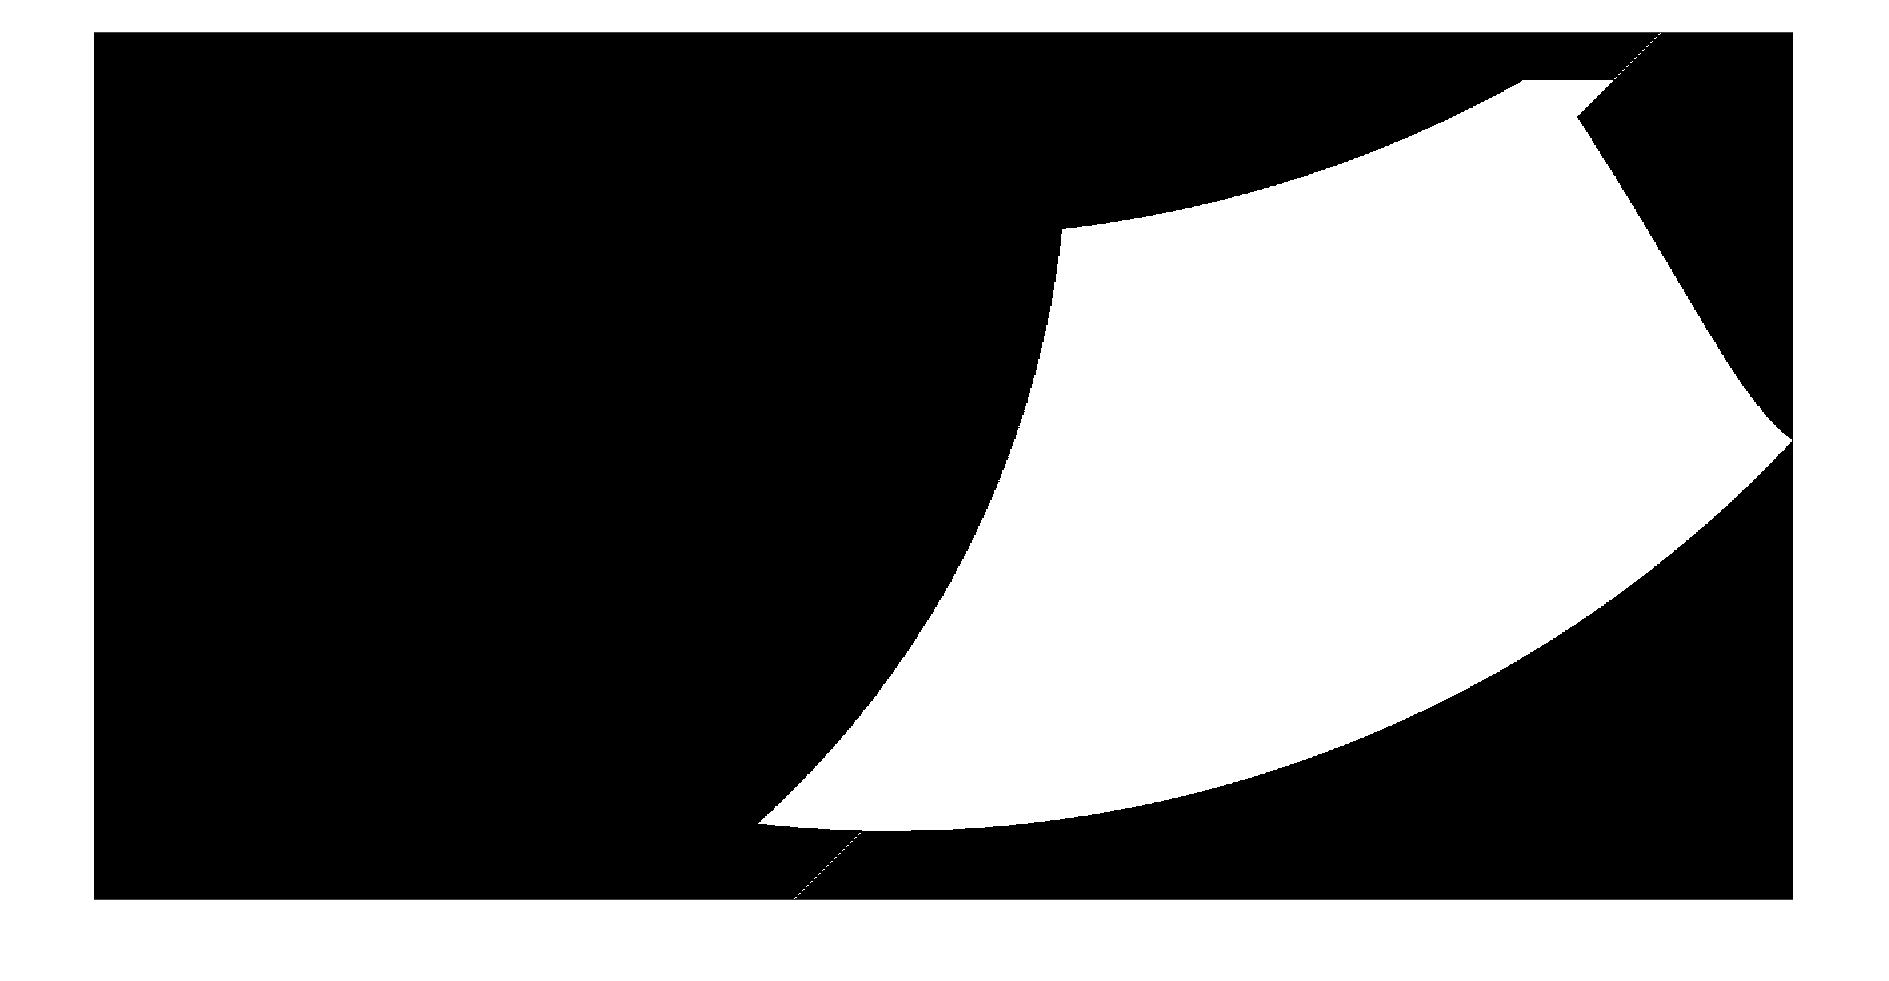


validPosmap2 = zeros((z_end-z_start)/acc+1,(r_end-r_start)/acc);
bounds = round(boundaries,Ndec, "decimals");
for i=1:length(boundaries)
    for j=bounds(i,1)*10^Ndec:bounds(i,2)*10^Ndec
        r = round(j);
        validPosmap2(i,r) = 1;
    end
end
imshow(flipud((validPosmap2)))

## Binary search for first valid position

The image above results in quite a good valid position map, but we still run into the fact that we sometimes don't start on a valid position. To solve this we can use the binary search again. Our guess as seen in the image above is actually very decent, and we only need to search in the area nearby the line, which simplyfies the computing time of the valid position map.

This binary search only needs to be applied to the bottem and the top, where we meet the edges of the area, because on all other points it is a simple solution. so first lets find those loctaions

tic
Ndec = 1;
acc = 1*10^-Ndec;
R_guess = zeros((z_end-z_start)/acc,1);
r_mid = (r_end + r_start )/ 2;
z_mid = (z_end + z_start)/2;
range = 10;
for i=1:(z_end-z_start)/acc %first creating the basic valid guess line
    z = i*acc;
    r = r_mid + (z-z_mid);
    min = r - range;
    max = r + range;
    R_guess(i) = VPBS.r_valid_guess(min,max,z,acc);
end
toc
plot(R_guess)

z_bottom_range = [100,110]/10;
z_top_range = [1150,1250]/10;


tic
Ndec = 2;
acc = 1*10^-Ndec;
R_guess = zeros((z_end-z_start)/acc,1);
r_mid = (r_end + r_start )/ 2;
z_mid = (z_end + z_start)/2;
for i=1:(z_end-z_start)/acc %first creating the basic valid guess line
    z = i*acc;
    R_guess(i) = r_mid + (z-z_mid);
end
for i=z_bottom_range(1)/acc:z_bottom_range(2)/acc
    z = i*acc;
    r = r_mid + (z-z_mid);
    min = r - range;
    max = r + range;
    R_guess(i) = VPBS.r_valid_guess(min,max,z,acc);
    if R_guess(i) == -50
        R_guess(i) = r;
    end
end

for i=z_top_range(1)/acc:z_top_range(2)/acc
    z = i*acc;
    r = r_mid + (z-z_mid);
    min = r - range;
    max = r + range;
    R_guess(i) = VPBS.r_valid_guess(min,max,z,acc/10);
    if R_guess(i) == -50
        R_guess(i) = r;
    end
end

toc
plot(R_guess)



tic
boundaries = zeros((z_end-z_start)/acc,2);
r_mid = (r_end + r_start )/ 2;
z_mid = (z_end + z_start)/2;
f = (z_end-z_start)/(length(boundaries)-10);
for i=1:(z_end-z_start)/acc
    z = i*acc;
    r = R_guess(i);
    boundaries(i,2) = VPBS.r_right(r,r_end,z,acc);
    boundaries(i,1) = VPBS.r_left(r_start,r,z,acc); 
end
toc

Elapsed time is 5.705032 seconds.


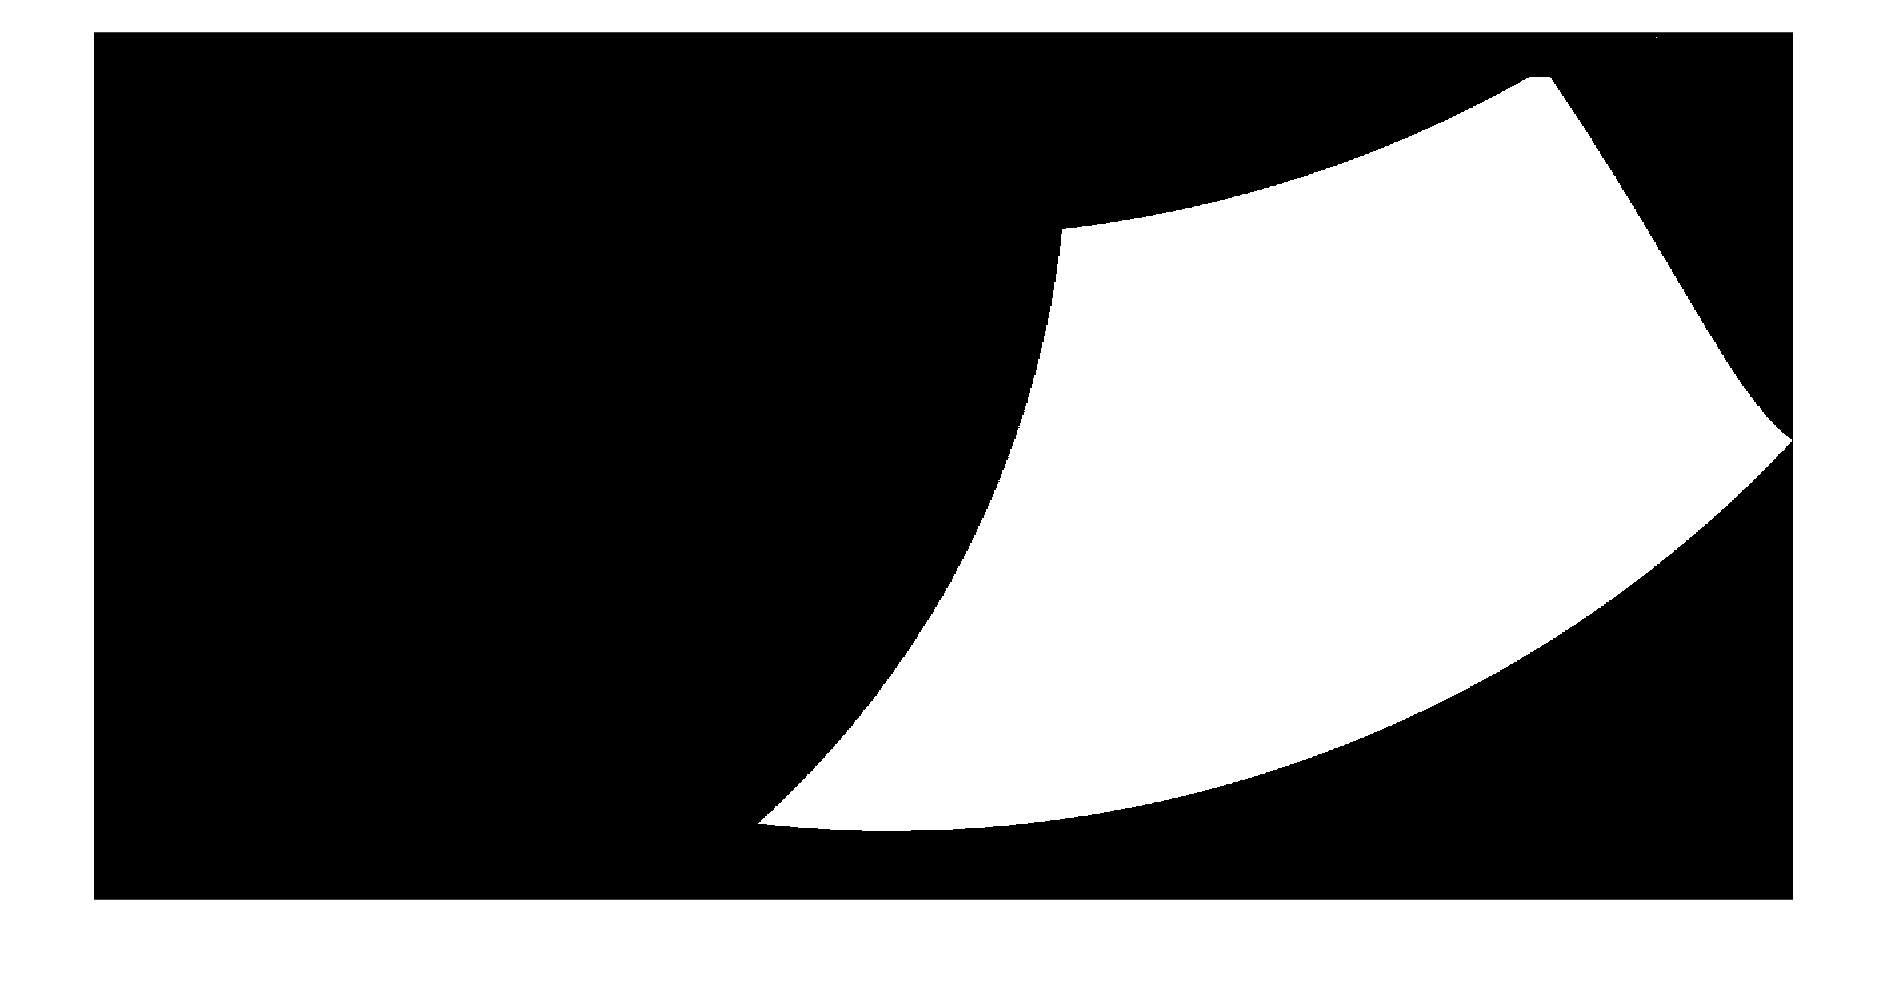


validPosmap2 = zeros((z_end-z_start)/acc+1,(r_end-r_start)/acc);
bounds = round(boundaries,Ndec, "decimals");
for i=1:length(boundaries)
    if bounds(i,1) == bounds(i,2)
        continue %there is only 1 valid position in the row, this means that now valid position has been found
    end
    for j=bounds(i,1)*10^Ndec:bounds(i,2)*10^Ndec
        r = round(j);
        validPosmap2(i,r) = 1;
    end
end
imshow(flipud((validPosmap2)))